# LEPTOSPIROSIS SIMULATION

#### **ESCENARIO II : PLAYA**

### **CASO I: MUCHO CONTACTO CERCANO CON HUMANOS**

####  1. Definimos los parámetros:

%Tasa de transmision de perros infectados a perros suceptibles
beta_p = 5*10^(-1);
%Tasa de transmision de leptospirosis de perros suscepitbles al estar en
%contacto con bacterias leptospira en el medio ambiente
beta_pb = 1*10^(-1);
%Tasa de transmision de leptospirosis de humanos suscepitbles al estar en
%contacto con bacterias leptospira en el medio ambiente
beta_hb = 0.1056;
%Tasa de transmision de perros infectados a humanos susceptibles
beta_hp = 0.44;
%Bacterias liberadas al medio por perro infeccioso
eta_p = 2*10^(-2);
%Bacterias liberadas al medio por humano infeccioso
eta_h = 2.1*10^(-7);
%Tasa de salida de animales
b = 1/365;
%Tasa de salida de bacterias
phi_b = 3;
%Tasa de recuperación de humanos asintomáticos
phi_ah = 1/14;
%Tasa de recuperación de humanos sintomáticos
phi_ih = 1/28;
%Tasa de mortalidad en humanos
mu = 0.15;

#### 2. Condiciones iniciales (en proporciones):

Si partimos de una población humana de 1000 personas en una playa y 700 perros.

%Población humana total 
Nh = 1000;
%Poblacion perros total
Np = 700;
%Poblacion bacterias lectospira inicial 
B0 = 10^(-1);
%Poblacion susceptible humana en t=0
Sh0 = 1;
%Poblacion susceptible perros en t=0
Sp0 = 0.99;
%Poblacion humanos asintomáticos en t=0
Ah0 = 0;
%Poblacion humanos sintomáticos en t=0
Ih0 = 0;
%Poblacion infectada perros en t=0
Ip0 = 0.01;
%Poblacion humanos recuperados en t=0
Rh0 = 0;
%Poblacion humanos muertos en t=0
Dh0 = 0;
%Ventana temporal de 60 días
tspan = [0 60];
%Porporción de humanos suscetibles que se convierten en asintomaticos:
a = 0.6;

#### 3. Sistema de ecuaciones diferenciales:

Notación:

y(1) = Sp;  y(2) = Ip; y(3) = Sh; y(4) = Ah; y(5) = Ih; y(6) = Rh; y(7) = Dh; y(8) = B

odefun = @(t, y) [-beta_p*y(1)*y(2) - beta_pb*y(1)*y(8)+ b*y(2); 
                  beta_p*y(1)*y(2) + beta_pb*y(1)*y(8) - b*y(2); 
                  -beta_hp*y(3)*y(2) - beta_hb*y(3)*y(8) ;
                  a*beta_hp*y(3)*y(2) + a*beta_hb*y(3)*y(8) - phi_ah*y(4);
                  (1-a)*beta_hp*y(3)*y(2) + (1-a)*beta_hb*y(3)*y(8) - phi_ih*y(5);
                  (1-mu)*phi_ih*y(5) + phi_ah*y(4);
                   mu*phi_ih*y(5);
                  eta_p*y(2) + eta_h*(y(4) + y(5)) - phi_b*y(8)];

#### 4. Resulevo el sistema:

% Solve the system
y0 = [Sp0; Ip0; Sh0; Ah0; Ih0; Rh0; Dh0; B0];
[t, y] = ode45(odefun, tspan, y0);

#### 5. Visualización de los resultados:

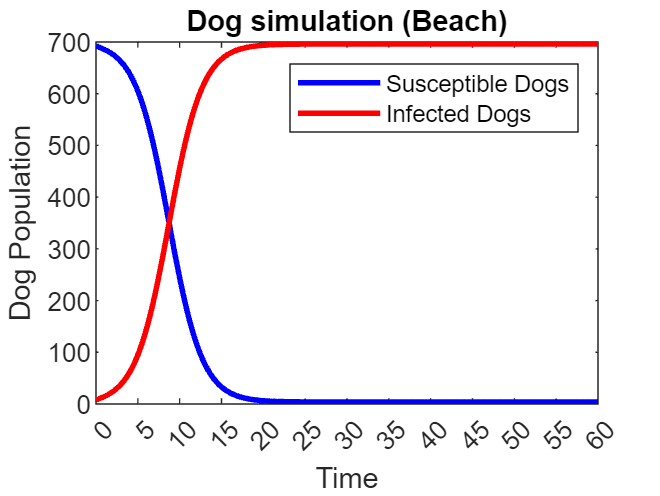

figure;
% Primero veo los resultados de la poblacion de animales
plot(t, Np*y(:,1), 'b', t, Np*y(:,2), 'r','LineWidth',2)
legend('Susceptible Dogs', 'Infected Dogs')
xlabel('Time');
xticks(0:5:t(end));
ylabel('Dog Population');
title('Dog simulation (Beach)');

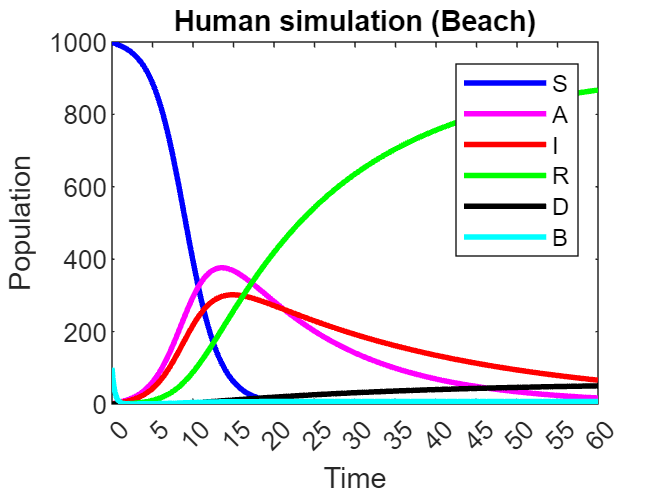

% Resultados para poblacion humana
plot(t, Nh*y(:,3), 'b', t, Nh*y(:,4), 'm', t, Nh*y(:,5), ...
    'r', t, Nh*y(:,6),'g', t, Nh*y(:,7), 'k', t, Nh*y(:,8), 'c', 'LineWidth',2);
legend('S', 'A', 'I', 'R', 'D', 'B');
xlabel('Time');
xticks(0:5:t(end));
ylabel('Population');
title('Human simulation (Beach)');

#### 6. Situación después de 2 meses:

%Numero total de perros que han sido infectados de los 700 perros totales:
inf_dog_tot = round(y(end,2)*Np);
%Con una proporción de:
inf_dog_perc = inf_dog_tot/Np*100;
%Numero total de humanos susceptibles de las 1000 personas totales:
sus_hum_tot = round(y(end,3)*Np);
%Con una proporción de:
sus_hum_perc = sus_hum_tot/Nh*100;
%Numero total de humanos que esta infectados de las 1000 personas totales:
inf_hum_tot = round((y(end,4) + y(end,5))*Nh);
%Con una proporción de:
inf_hum_perc = inf_hum_tot/Nh*100;
%Numero total de humanos que esta recuperados de las 1000 personas totales:
rec_hum_tot = round(y(end,6)*Nh);
%Con una proporción de:
rec_hum_perc = rec_hum_tot/Nh*100;
%Numero total de humanos que han fallecido de las 1000 personas totales:
dead_hum_tot = round(y(end,7)*Nh);
%Con una proporción de:
dead_hum_perc = dead_hum_tot/Nh*100;
%Resultados
disp('Results after 2 months:');

Results after 2 months:


disp(['Total Infected Dogs: ' num2str(inf_dog_tot)])

Total Infected Dogs: 696


disp(['Percentage of Infected Dogs: ' num2str(inf_dog_perc) '%']);

Percentage of Infected Dogs: 99.4286%


disp(['Total Susceptible Humans: ' num2str(sus_hum_tot)]);

Total Susceptible Humans: 0


disp(['Percentage of Susceptible Humans: ' num2str(sus_hum_perc) '%']);

Percentage of Susceptible Humans: 0%


disp(['Total Infected Humans: ' num2str(inf_hum_tot)]);

Total Infected Humans: 82


disp(['Percentage of Infected Humans: ' num2str(inf_hum_perc) '%']);

Percentage of Infected Humans: 8.2%


disp(['Total Recovered Humans: ' num2str(rec_hum_tot)]);

Total Recovered Humans: 867


disp(['Percentage of Recovered Humans: ' num2str(rec_hum_perc) '%']);

Percentage of Recovered Humans: 86.7%


disp(['Total Dead Humans: ' num2str(dead_hum_tot)]);

Total Dead Humans: 50


disp(['Percentage of Dead Humans: ' num2str(dead_hum_perc) '%']);

Percentage of Dead Humans: 5%


disp('------------------------------------------------------');

------------------------------------------------------


#### 7. Resultados notables:

% Cantidad de humanos infectados en el pico de la enfermedad:
Max_quant_inf_hum = round(max(y(:,4))*Nh  + max(y(:,5))*Nh);
% De los cuales asimtomaticos:
ah_max = round(max(y(:,4))*Nh);
% De los cuales simtomaticos:
ih_max = round(max(y(:,5))*Nh);
disp('At the peak of the infection:');

At the peak of the infection:


disp(['Total Infected Humans: ' num2str(Max_quant_inf_hum)]);

Total Infected Humans: 678


disp(['Total Infected Asymptomatic Humans: ' num2str(ah_max)]);

Total Infected Asymptomatic Humans: 376


disp(['Total Infected Symptomatic Humans: ' num2str(ih_max)]);

Total Infected Symptomatic Humans: 302
